# TCLab Temperature Sensor

**Objective**: Use the TMP36 sensor correlation for converting between voltage signal and temperature.

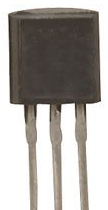

The two temperature sensors on the TCLab are TMP36GZ thermistors that report an output voltage (mV) that is linearly proportional to temperature


$$T^oC = 0.1 \, mV-50$$


TMP36 sensor accuracy is $\pm 1^oC$ at $25^oC$ and $\pm 2^oC$ over the range $-40^oC$ to $150^oC$.

- What is the gain, zero, and span of the TMP36 thermistor?

  question1

Gain: 10 mV per degree C
Span: 190 degrees C
Zero: -40 C


- What mV signal corresponds to $25^oC$?

  question2

function mV = mV_from_T(T)
mV = round((T+50.0)*10.0,2);
end

mV signal at 25 degC: mV_from_T(25)
   750



- What mV signal corresponds $80^oC$?

  question3

function mV = mV_from_T(T)
    mV = round((T+50.0)*10.0,2);
end

mV signal at 25 degC: mV_from_T(80)
        1300



- What temperature corresponds to a 0.5V signal?

  question4

function T = T_from_mV(mv)
    T = round(0.1 * mV - 50.0, 1);
end

T at 0.5 V: T_from_mV(500)
     0



- What temperature corresponds to a 1.2V signal?

  question5

function T = T_from_mV(mv)
    T = round(0.1 * mV - 50.0, 1);
end

T at 1.2 V: T_from_mV(1200)
    70



- Print the current temperature for $T_1$ and $T_2$ in Celsius and milliVolts.

  question6

lab=tclab
T1 = lab.T1;
T2 = lab.T2
T1mV = (T1+50.0)*10.0
T2mV = (T2+50.0)*10.0


lab = tclab

lab =   tclab with properties:

      device: 'TCLab'
       board: 'Leonardo'
    platform: 'matlab'
         lab: [1×1 arduino]


T1 = lab.T1

T1 = 21.2121

T2 = lab.T2

T2 = 21.3587

T1mV = (T1 + 50.0) * 10.0

T1mV = 712.1212

T2mV = (T2 + 50.0) * 10.0

T2mV = 713.5875

**Additional Information (Not Required)**

The mV is read on the Arduino with a 10-bit Analog to Digital Converter (ADC). There are 210 discrete levels (DL) with a 10-bit ADC between 0 and 3300 mV. The Arduino reports a DL integer between 0 and 1023. This is converted to milliVolts with $mV=DL \frac{3300}{1024}$. The following is a code segment from the firmware (C code) that is [**loaded on the Arduino**](https://youtu.be/jbUFqL_dkZA).

`// Arduino code tclab.ino`

`const` `int` `pinT1  ` `=` `0``;`

`const` `int` `pinT2  ` `=` `2``;`

`float` `mV` `=` `0.0``;`

`float` `degC` `=` `0.0``;`

`for` `(``int` `i` `=` `0``;` `i` `<` `n``;` `i``++``)` `{`

`  mV` `=` `(``float``)` `analogRead``(``pinT1``)` `*` `(``3300.0``/``1024.0``)``;`

`  degC` `=` `degC` `+` `(``mV` `-` `500.0``)``/``10.0``;`

`}`

`degC` `=` `degC` `/` `float``(``n``)``;`  

`Serial.``println``(``degC``)``;`

Temperature 1 ($T_1$) is from pin 0 and temperature 2 ($T_2$) is from pin 2 on the Arduino as shown in the instrumentation wiring schematic.

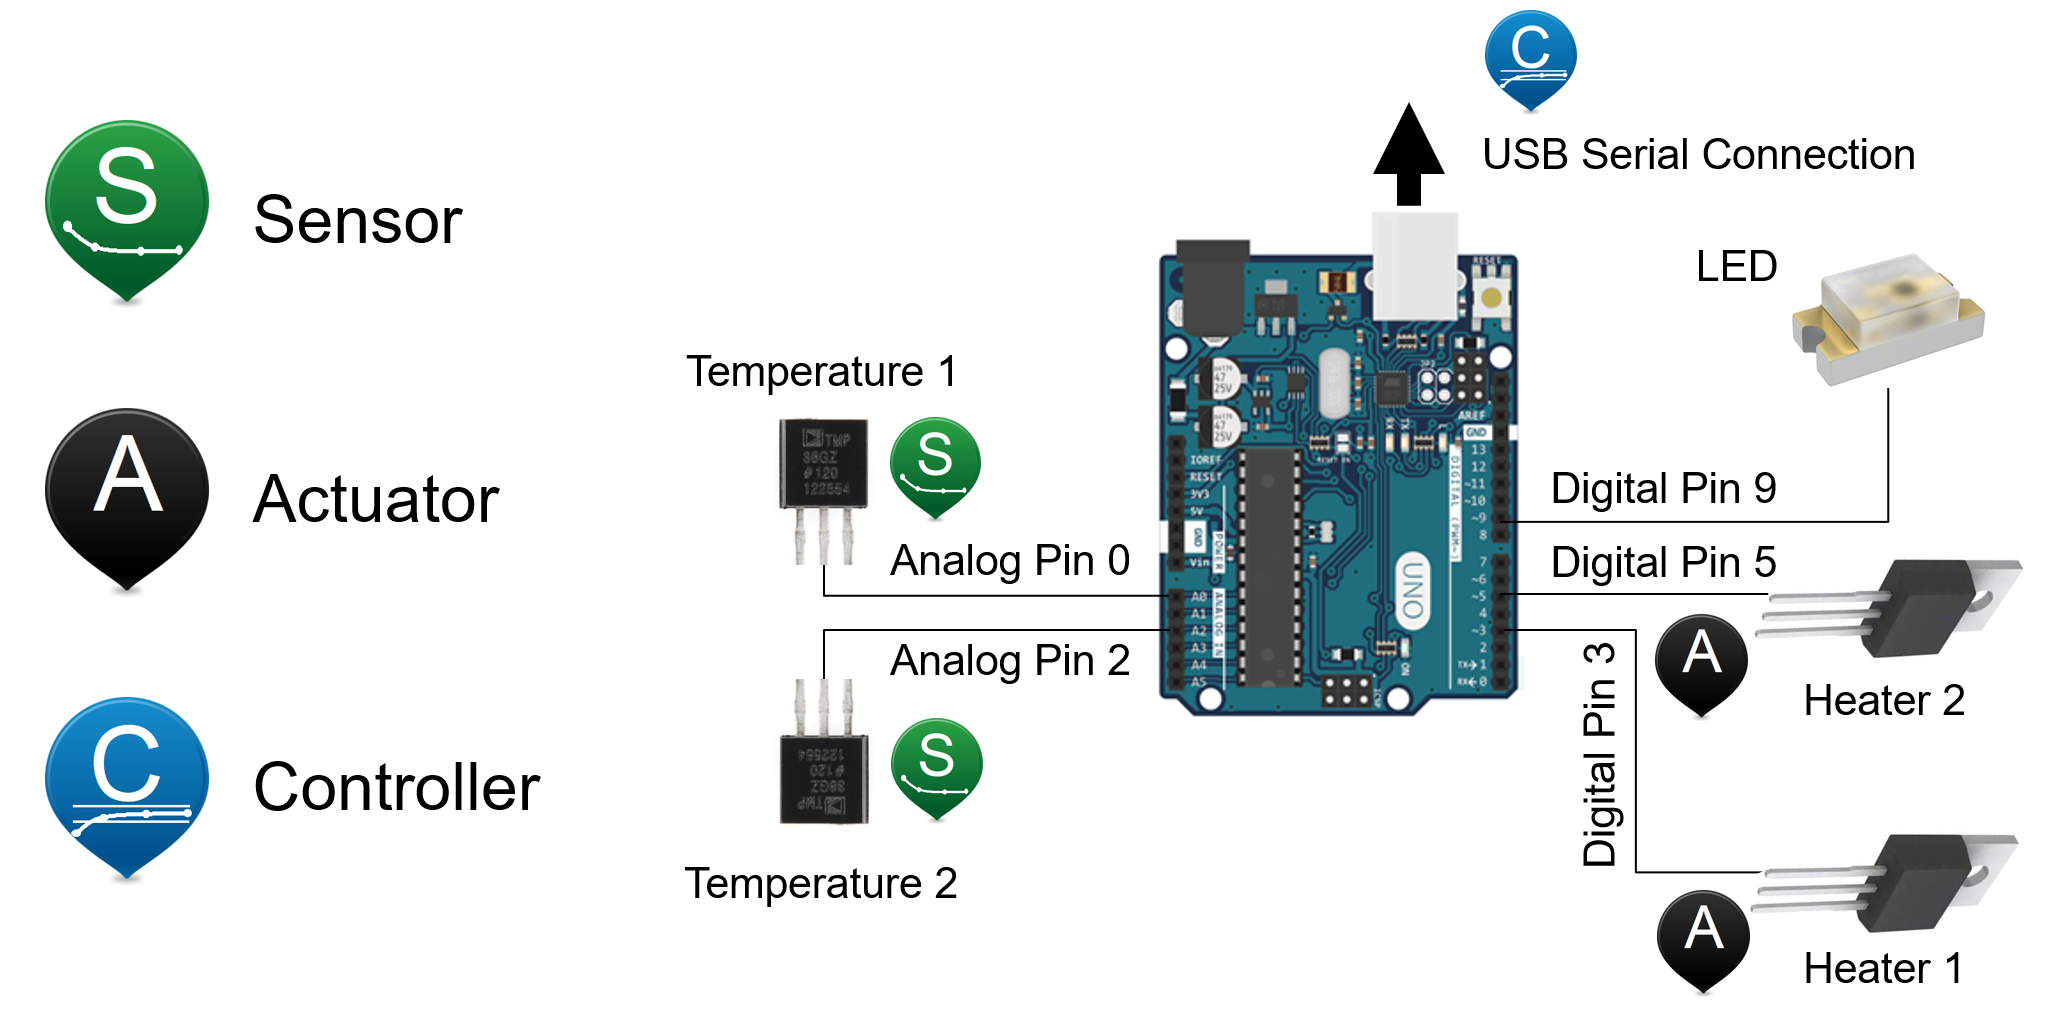

The temperature is read 10 times in rapid succession and then an average is reported over the serial interface. The temperature is reported over the serial (USB) connection when Python requests a value for $T_1$.

The assignment for this module is to answer the bulleted questions above.

### Solution Video

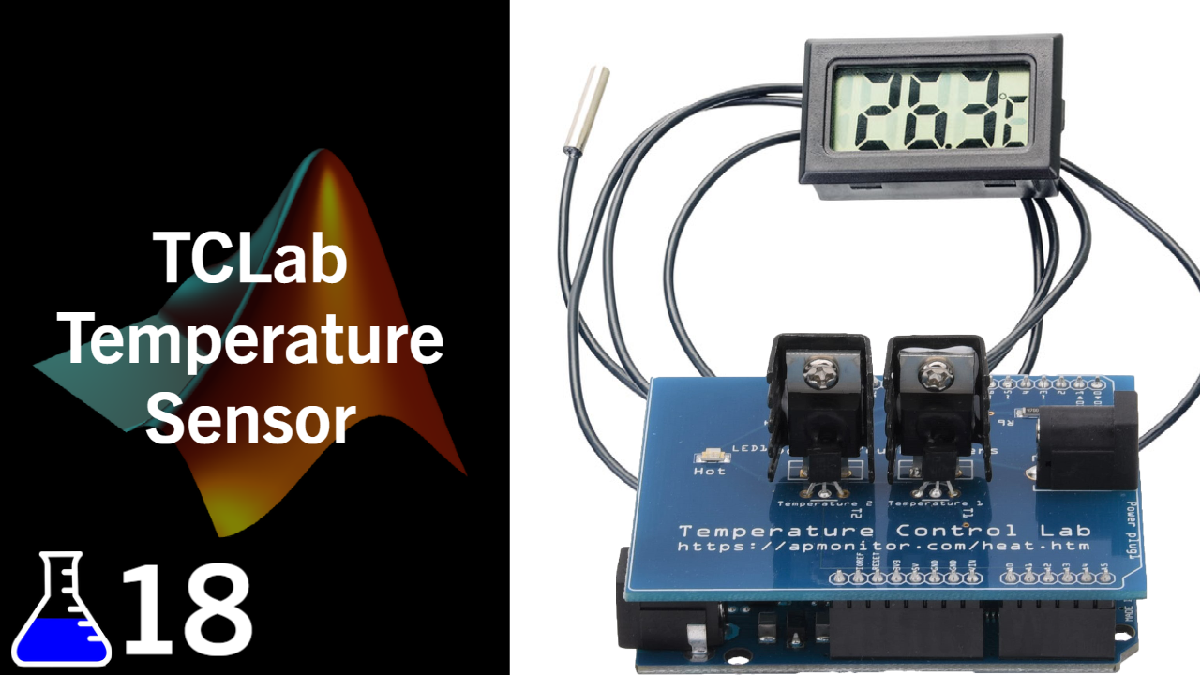

### [View Video](https://youtu.be/9-z9m9jaCN8)

function question1()
disp("Gain: 10 mV per degree C" + newline + ...
     "Span: 190 degrees C" + newline + ...
     "Zero: -40 C")
end

function question2()
disp("function mV = mV_from_T(T)" + newline + ...
    "mV = round((T+50.0)*10.0,2);" + newline + ...
    "end" + newline + newline + ...
    "mV signal at 25 degC: mV_from_T(25)")
disp(mV_from_T(25))
end

function question3()
disp("function mV = mV_from_T(T)" + newline + ...
    "    mV = round((T+50.0)*10.0,2);" + newline + ...
    "end" + newline + newline + ...
    "mV signal at 25 degC: mV_from_T(80)")
disp(mV_from_T(80))
end

function question4()
disp("function T = T_from_mV(mv)" + newline + ...
    "    T = round(0.1 * mV - 50.0, 1);" + newline + ...
    "end" + newline + newline + ...
    "T at 0.5 V: T_from_mV(500)")
disp(T_from_mV(500))
end

function question5()
disp("function T = T_from_mV(mv)" + newline + ...
    "    T = round(0.1 * mV - 50.0, 1);" + newline + ...
    "end" + newline + newline + ...
    "T at 1.2 V: T_from_mV(1200)")
disp(T_from_mV(1200))
end

function question6()
disp("lab=tclab" + newline + ...
    "T1 = lab.T1;" + newline + ...
    "T2 = lab.T2" + newline  + ...
    "T1mV = (T1+50.0)*10.0" + newline  + ...
    "T2mV = (T2+50.0)*10.0")
end

function T = T_from_mV(mV)
    T = round(0.1 * mV - 50.0, 1);
end
function mV = mV_from_T(T)
    mV = round((T+50.0)*10.0,2);
end